# Temperature - Simulation

## 1.

Run `tempReg.mlx`. **Note** You may want to use the Distribution Fitting app to find a suitable distribution for the temperature residuals before proceeding.

tempReg

time = 	1.0e+03 *

         0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0004


model = function_handle with value:
    @(b,t)b(1)+b(2)*t+b(3)*sin(2*pi*t/365+b(4))+b(5)*sin(2*pi*t+b(6))

b0 =    10.0000
         0
   15.0000
   -1.5708
    5.0000
   -1.5708


tempFit = Nonlinear regression model:
    y ~ b1 + b2*t + b3*sin(2*pi*t/365 + b4) + b5*sin(2*pi*t + b6)

Estimated Coefficients:
           Estimate         SE          tStat       pValue 
          __________    __________    __________    _______
    b1        9.9396       0.03881        256.11          0
    b2    2.1341e-08    3.0732e-05    0.00069442    0.99945
    b3        12.663      0.027297         463.9          0
    b4       -1.9947     0.0021696       -919.41          0
    b5        3.1703      0.027269        116.26          0
    b6       -2.4928     0.0086013       -289.81          0

Number of observations: 52608, Error degrees of freedom: 52602
Root Mean Squared Error: 4.42
R-Squared: 0.813,  Adjusted R-Squared 0.813
F-statistic vs.

close('all','force')

## 2.

Fit a normal distribution to the vector of temperature residuals.

tempRDist = fitdist(tempResiduals,'normal')

tempRDist =   NormalDistribution

  Normal distribution
       mu = -3.43148e-13   [-0.0377911, 0.0377911]
    sigma =       4.4224   [4.39584, 4.44928]


## 3.

Seed the random number generator at the MATLAB default value. Then generate random residuals for the first quarter of a year (hourly data for days 0 to 90).

rng('default')
rndTempResiduals = random(tempRDist,90*24+1,1)

rndTempResiduals =     2.3778
    8.1102
   -9.9895
    3.8129
    1.4097
   -5.7831
   -1.9175
    1.5152
   15.8251
   12.2476


## 4.

Calculate a simulated temperature curve by evaluating the fitted deterministic model and adding the simulated residuals. 

**Hint** For evaluating the model, you can use the following syntax:

`temp = model(b,0:1/24:90);`

time = (0:1/24:90)';
b = tempFit.Coefficients.Estimate;
simTemp = model(b,time) + rndTempResiduals

simTemp =    -1.1403
    3.9998
  -14.5215
   -0.9415
   -3.3531
  -10.3400
   -6.0683
   -2.0574
   12.9631
   10.1801


## 5.

Display the simulated temperature curve in a plot.

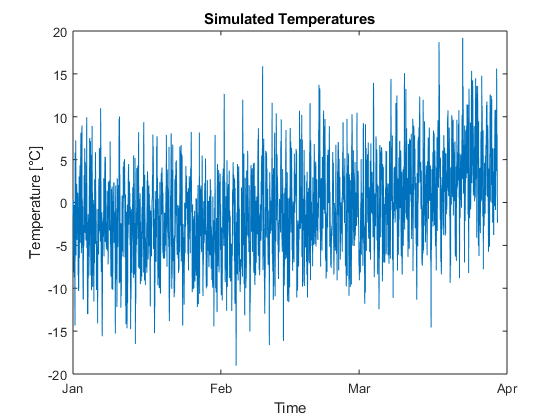

plot(time,simTemp)
datetick('x','mmm')
ylabel('Temperature [°C]')
xlabel('Time')
title('Simulated Temperatures')